clear; close; clc;

## Define Parameters

% performace
W = 700*9.81; % weight in Newtons
W2S = 500; % wing loading in newtons per square meter

% Critical geometery
A = 29; % aspect ratio
b = 20; % m

% free to choose geometery (Note: wing becomes degenerate with transition
% further outboard)
s_i = 3; % inboard section semispan
s_o = 7; % outbaord section span
%s_o = convlength(100,"in","m")
lambda = .4; % taper ratio of equivalent wing
lambda_i = 1; % imboard taper ratio

%Lambda_i = deg2rad(0); % leading edge sweep angle of inboard section - this wont work due to AC alignment
Lambda_i = deg2rad(5); % leading edge sweep angle of inboard section - 5 deg works well for 2 and 3 segment wings
%Lambda_i = deg2rad(10); % leading edge sweep angle of inboard section - 10
%deg is agressive almost always degenerate

## Compute Wing Section


[cr, ct, c_bar] = solveWing(A, b, lambda)

cr = 0.9852

ct = 0.3941

c_bar = 0.7319


S = b^2/A;


lambda_o = (lambda*(s_o+s_i) - s_i*lambda_i) / s_o

lambda_o = 0.1429


c_bar_i = c_bar * (s_i+s_o) / (s_i + 2/3 * s_o * (1 + lambda_o + lambda_o^2) / (1+lambda_o))

c_bar_i = 0.9444


c_bar_o = 2/3 * c_bar_i * (1 + lambda_o + lambda_o^2) / (1+lambda_o)

c_bar_o = 0.6408


c_t = c_bar_i*lambda_o

c_t = 0.1349


delta_y_sweep_i = s_i * sin(Lambda_i)

delta_y_sweep_i = 0.2615


% layout locations for points

% 2 segment - valid ON THE case deSCRIBED BELOW - LOOKS STRANGE - WORKS UNSWEPT
% % xcoordinate of points
% x_coords = [0, s_i, b/2, b/2, s_i, 0] % LE inboard center,  LE joint location, LE outboard tip, TE inboard center,  TE joint location, TE outboard tip
% % ycoordingates of points
% y_coords = [0, delta_y_sweep_i, 0, -c_t, delta_y_sweep_i - c_bar_o, -c_bar_o]

% % 3 segment - this is outboard sweep change (cresent wing) - VALID AS
% BELOW BUT STRANGE
% xcoordinate of points
% x_coords = [0, s_i, (s_i +b/2)/2, b/2, b/2, (s_i +b/2)/2, s_i, 0] % LE inboard center,  LE joint location, LE outboard tip, TE inboard center,  TE joint location, TE outboard tip
% % ycoordingates of points
% y_coords = [0, (s_i +b/2)/2 * sin(Lambda_i), ((s_i + b/2)/2 * sin(Lambda_i) + c_t)/2, 0, -c_t,  (s_i +b/2)/2 * sin(Lambda_i) - c_bar_o, (s_i +b/2)/2 * sin(Lambda_i) - c_bar_o, -c_bar_o]

% 3 segment - this is outboard sweep change (cresent wing) - VALID - BEST PERFORMANCE
% THIS ONE WORKS WITH THE FOLLOWING SETTINGS
% s_i = 3
% s_o = 7 
% Lambda_i = 5
% lambda = .4;
% lambda_i = 1;
% xcoordinate of points
x_coords = [0, s_i, (s_i +b/2)/2, b/2, b/2, (s_i +b/2)/2, s_i, 0] % LE inboard center,  LE joint location, LE outboard tip, TE inboard center,  TE joint location, TE outboard tip

x_coords =          0    3.0000    6.5000   10.0000   10.0000    6.5000    3.0000         0


% ycoordingates of points
y_coords = [0, (s_i +b/2)/2 * sin(Lambda_i), ((s_i+b/2)/2*sin(Lambda_i) + c_t)/2 + c_t, 0, -c_t,  (s_i +b/2)/2 * sin(Lambda_i) - c_bar_o + c_t, (s_i +b/2)/2 * sin(Lambda_i) - c_bar_i, -c_bar_i]

y_coords =          0    0.5665    0.4856         0   -0.1349    0.0606   -0.3778   -0.9444


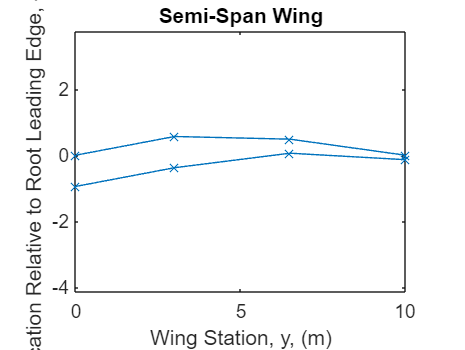

% plot wings
figure;

plot(x_coords, y_coords, "-x");
title("Semi-Span Wing"); xlabel("Wing Station, y, (m)"); ylabel("Location Relative to Root Leading Edge, -x, (m)");
axis equal;

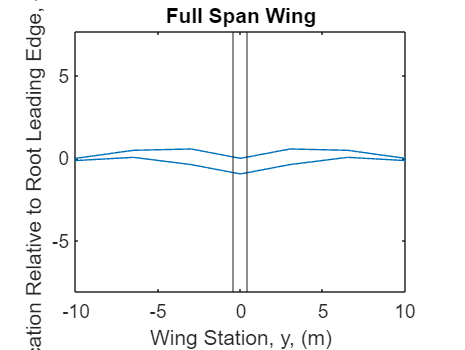


figure;
plot([x_coords, -fliplr(x_coords)], [y_coords,fliplr(y_coords)])
title("Full Span Wing"); xlabel("Wing Station, y, (m)"); ylabel("Location Relative to Root Leading Edge, -x, (m)");
axis equal;

xline(.4,"-");
xline(-.4,"-")


% save wing coordinates for use in other files
wingCoordinates = [x_coords; y_coords];
save("Arychtas_Wing_Coordinates_Class_I_V_0.mat","wingCoordinates")


function [cr_val, ct_val, cbar_val] = solveWing(A_val, b_val, lambda_val)
    syms A b cr lambda cbar ct
    
    eq1 = A == (2*b)/(cr*(1 + lambda));
    eq2 = cbar == 2/3*cr*((1+lambda + lambda^2)/(1+lambda));
    eq3 = lambda == ct/cr;

    sol = solve([eq1, eq2, eq3], [cr, ct, cbar]);

    cr_sym = sol.cr;
    ct_sym = sol.ct;
    cbar_sym = sol.cbar;

    % Substitute known values to get numerical results
    cr_val = double(subs(cr_sym, {A, b, lambda}, {A_val, b_val, lambda_val}));
    ct_val = double(subs(ct_sym, {A, b, lambda}, {A_val, b_val, lambda_val}));
    cbar_val = double(subs(cbar_sym, {A, b, lambda}, {A_val, b_val, lambda_val}));
end
